**ENGN1930B Homework 4**

**Name: Kuan-Min Lee**

**Instructor: Dr. Jonghwan Lee**

**Problem 2.3**

% parameter settings
delta=0; % initial phase for plane wave
k_hat=[1 2 3]/norm([1 2 3]);
power=1e-3; % light power  for laser (1.0 mW)
D=3e-3; % beam diameter for laser (3.0 mm)
wlength=500e-9; % wavelength of laser beam (500 nm)
c=3e8; % light speed 
n=1; % reflective index in air
permitivity_air=8.854e-12; % permittivity of air (8.854*10^(-14) F/m)

f=c/wlength; % calculate frequency for laser
omega=2*pi*f; % calculate angular frequency
k=omega/c*k_hat; % calculate k vector
msg=strcat("The frequency of laser is ", string(num2str(f,'%.e')), " Hz.");
msg

msg = "The frequency of laser is 6e+14 Hz."

area=pi*(D/2)^2; % calculate the area
inten_laser=power/area; % calculate the intensity based on the fact that intensity=power/area
amp_laser=sqrt(2*inten_laser/(n*c*permitivity_air)); % calculate the amplitude of the electric field based intensity formula
msg=strcat("The amplitude of electric field is ", string(num2str(amp_laser,'%.e')), " V/m.");
msg

msg = "The amplitude of electric field is 3e+02 V/m."

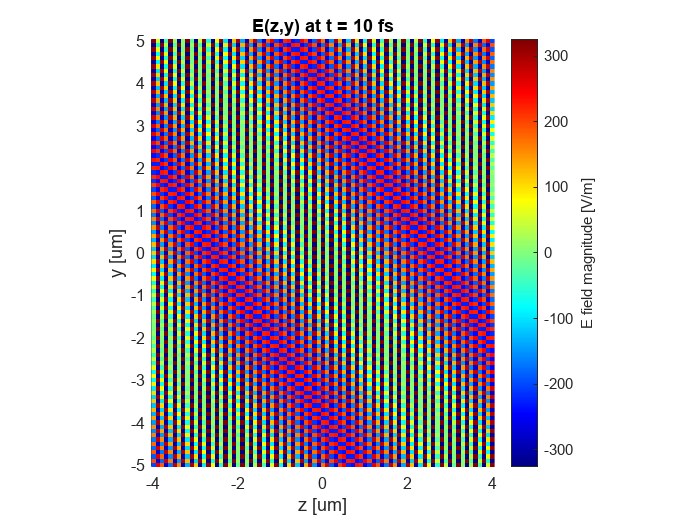

% setup for plotting
dz=0.1;
y=-5:dz:5; % setup y range
z=-4:dz:4; % setup z range
[gy,gz]=ndgrid(y,z); % setup meshgrid
tMax=10e-15; % setup the maximum time
dt=0.1e-15; % setup the time displacement
t=0:dt:tMax;
nt=length(t);

% Make the video
v = VideoWriter('ENGN1930B_HW4_Prob23_n.mp4','MPEG-4');
v.Quality=95;
v.FrameRate=10;
open(v);

figure; colormap(jet);
hold on;
for it=1:nt
    t1=t(it);

    E=amp_laser * cos(k(1)*0 + k(2)*gy + k(3)*gz - omega*t1);
    imagesc(z,y,E);
    set(gca,'ydir','normal');
    axis image;
    set(gca, 'clim', [-amp_laser amp_laser]);
    cb=colorbar;
    cb.Label.String='E field magnitude [V/m]';
    xlabel('z [um]')
    ylabel('y [um]')
    title(['E(z,y) at t = ' num2str(t1*1e15) ' fs']);
    frm=getframe(gcf);
    writeVideo(v,frm);
end

**Problem 2.4:**

clear all

n=1; % reflective index
c=3e8; % light of speed oin vacuum
permitivity_air=8.854e-12; % permittivity of air (8.854*10^(-14) F/m)

% setup parameters for E1 and E2 function
syms E01 E02 k z omega t delta

E1(delta) = E01*exp(i*(k*z-omega*t+delta)); % E1 function
E2 = E02*exp(i*(k*z-omega*t)); % E2 function
superimposed_E(delta)=E1(delta)+E2; % get the superimposed electric field
conj_superimposed_E(delta)=conj(superimposed_E(delta)); % get the complex conjugate of superimposed electric field
I_E(delta)=1/2*n*c*permitivity_air*superimposed_E(delta)*conj_superimposed_E(delta);
fprintf("The intensity is:")

The intensity is:

I_E

$$I\_E(delta) = \left(\frac{6124780201073413\,E_{01}\,{\mathrm{e}}^{\delta \,\mathrm{i}-\omega \,t\,\mathrm{i}+k\,z\,\mathrm{i}}}{4611686018427387904}+\frac{6124780201073413\,E_{02}\,{\mathrm{e}}^{-\omega \,t\,\mathrm{i}+k\,z\,\mathrm{i}}}{4611686018427387904}\right)\,\left({\mathrm{e}}^{-\bar{\delta }\,\mathrm{i}+\bar{\omega }\,\bar{t}\,\mathrm{i}-\bar{k}\,\bar{z}\,\mathrm{i}}\,\bar{E_{01}}+{\mathrm{e}}^{\bar{\omega }\,\bar{t}\,\mathrm{i}-\bar{k}\,\bar{z}\,\mathrm{i}}\,\bar{E_{02}}\right)$$

fprintf("W/m^2")

W/m^2

delta1=pi; % when delta equals to pi
fprintf("When delta equals to pi:")

When delta equals to pi:

I_E(delta1)

$$ans = \left({\mathrm{e}}^{\bar{\omega }\,\bar{t}\,\mathrm{i}-\bar{k}\,\bar{z}\,\mathrm{i}}\,\bar{E_{01}}-{\mathrm{e}}^{\bar{\omega }\,\bar{t}\,\mathrm{i}-\bar{k}\,\bar{z}\,\mathrm{i}}\,\bar{E_{02}}\right)\,\left(\frac{6124780201073413\,E_{01}\,{\mathrm{e}}^{-\omega \,t\,\mathrm{i}+k\,z\,\mathrm{i}}}{4611686018427387904}-\frac{6124780201073413\,E_{02}\,{\mathrm{e}}^{-\omega \,t\,\mathrm{i}+k\,z\,\mathrm{i}}}{4611686018427387904}\right)$$

delta2=pi/2; % when delta equals to pi
fprintf("When delta equals to pi:")

When delta equals to pi:

I_E(delta2)

$$ans = \begin{array}{l} \left({\mathrm{e}}^{-\frac{\pi \,\mathrm{i}}{2}+\sigma_{2}-\sigma_{1}}\,\bar{E_{01}}+{\mathrm{e}}^{\sigma_{2}-\sigma_{1}}\,\bar{E_{02}}\right)\,\left(\frac{6124780201073413\,E_{01}\,{\mathrm{e}}^{\frac{\pi \,\mathrm{i}}{2}-\omega \,t\,\mathrm{i}+k\,z\,\mathrm{i}}}{4611686018427387904}+\frac{6124780201073413\,E_{02}\,{\mathrm{e}}^{-\omega \,t\,\mathrm{i}+k\,z\,\mathrm{i}}}{4611686018427387904}\right)\\ \mathrm{where}\\ \sigma_{1}=\bar{k}\,\bar{z}\,\mathrm{i}\\ \sigma_{2}=\bar{\omega }\,\bar{t}\,\mathrm{i} \end{array}$$

**Problem 2.5:**

% set up parameters
syms rho z % rho: distance on x-y plane, z
theta=rho/z % define angle as distance on x-y plane divided by the distance on z plane (paraxial assumption)

$$theta = \frac{\rho }{z}$$

% set up parameters
syms theta 
r=z*(1+1/2*theta^2-1/8*theta^4) %  r: overall distance

$$r = z\,\left(-\frac{\theta^{4}}{8}+\frac{\theta^{2}}{2}+1\right)$$

syms lambda % lambda: wavelength
syms ampE % ampE: amplitude of electric field
E=ampE/z*exp(i*2*pi/lambda*z*1)*exp(i*2*pi/lambda*z*1/2*theta^2)*exp(i*2*pi/lambda*z*(-1/8*theta^4)) %  E: electric field

$$E = \frac{\mathrm{ampE}\,{\mathrm{e}}^{\frac{\pi \,\theta^{2}\,z\,\mathrm{i}}{\lambda }}\,{\mathrm{e}}^{-\frac{\pi \,\theta^{4}\,z\,\mathrm{i}}{4\,\lambda }}\,{\mathrm{e}}^{\frac{2\,\pi \,z\,\mathrm{i}}{\lambda }}}{z}$$

(2*pi/lambda)*z*(-1/8)*theta^4 == (2*pi/lambda)*z*(-1/8)*(rho/z)^4

$$ans = -\frac{\pi \,\theta^{4}\,z}{4\,\lambda }=-\frac{\pi \,\rho^{4}}{4\,\lambda \,z^{3}}$$

(2*pi/lambda)*z*(-1/8)*(rho/z)^4 < pi

$$ans = -\frac{\pi \,\rho^{4}}{4\,\lambda \,z^{3}}<\pi$$

rho^4 < 4*lambda*z^3

$$ans = \rho^{4}<4\,\lambda \,z^{3}$$